% Standard form LP with random data
%Generate problem data
randn('state', 0);
rand('state', 0);

n = 5;  % dimension of x
m = 4;  % number of equality constraints

c  = rand(n,1) + 0.5;    % create nonnegative price vector with mean 1
x0 = abs(randn(n,1));    % create random solution vector

A = abs(randn(m,n));     % create random, nonnegative matrix A
b = A*x0;

%Solve problem
[x history] = linprog(c, A, b, 1.0, 1.0);

iter	    r norm	   eps pri	    s norm	  eps dual	 objective
  1	    0.0000	    0.0209	    2.0673	    0.0002	      3.91
  2	    0.0824	    0.0227	    0.4471	    0.0010	      3.64
  3	    0.4063	    0.0247	    0.1864	    0.0051	      3.45
  4	    0.1817	    0.0233	    0.1293	    0.0069	      3.58
  5	    0.0107	    0.0223	    0.1107	    0.0068	      3.70
  6	    0.0505	    0.0221	    0.0229	    0.0063	      3.72
  7	    0.0225	    0.0222	    0.0161	    0.0061	      3.70
  8	    0.0014	    0.0223	    0.0137	    0.0061	      3.69
  9	    0.0063	    0.0224	    0.0028	    0.0062	      3.69
Elapsed time is 0.014902 seconds.


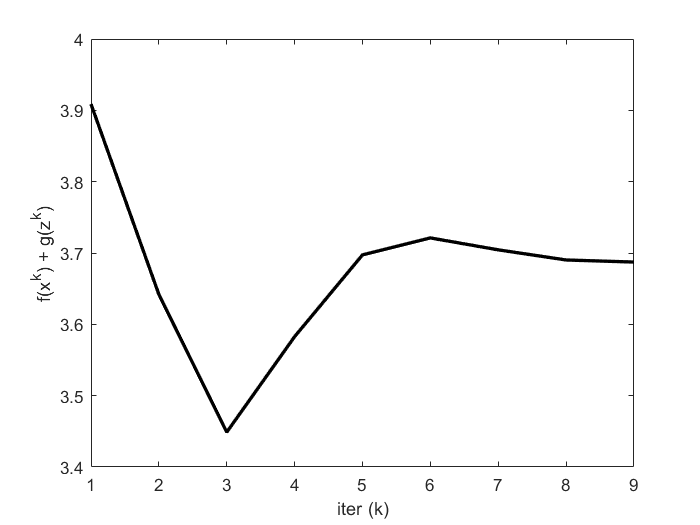

%Reporting
K = length(history.objval);

h = figure;
plot(1:K, history.objval, 'k', 'MarkerSize', 10, 'LineWidth', 2);
ylabel('f(x^k) + g(z^k)'); xlabel('iter (k)');

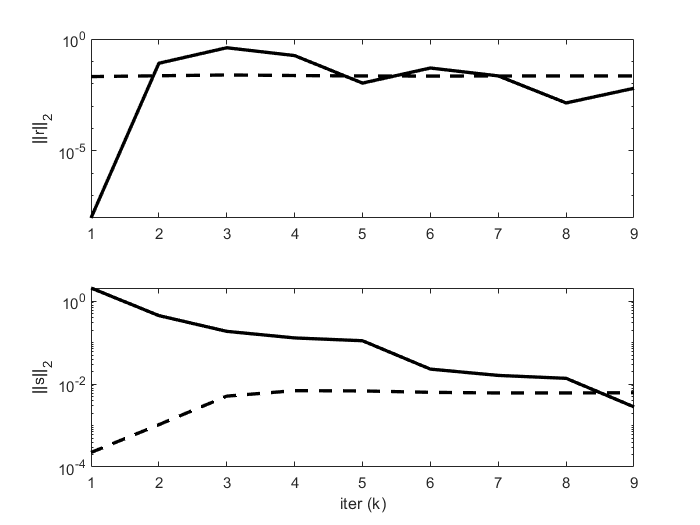

g = figure;
subplot(2,1,1);
semilogy(1:K, max(1e-8, history.r_norm), 'k', ...
    1:K, history.eps_pri, 'k--',  'LineWidth', 2);
ylabel('||r||_2');

subplot(2,1,2);
semilogy(1:K, max(1e-8, history.s_norm), 'k', ...
    1:K, history.eps_dual, 'k--', 'LineWidth', 2);
ylabel('||s||_2'); xlabel('iter (k)');

function [z, history] = linprog(c, A, b, rho, alpha)
% linprog  Solve standard form LP via ADMM
%
% [x, history] = linprog(c, A, b, rho, alpha);
%
% Solves the following problem via ADMM:
%
%   minimize     c'*x
%   subject to   Ax = b, x >= 0
%
% The solution is returned in the vector x.
%
% history is a structure that contains the objective value, the primal and
% dual residual norms, and the tolerances for the primal and dual residual
% norms at each iteration.
%
% rho is the augmented Lagrangian parameter.
%
% alpha is the over-relaxation parameter (typical values for alpha are
% between 1.0 and 1.8).
%
%
% More information can be found in the paper linked at:
% http://www.stanford.edu/~boyd/papers/distr_opt_stat_learning_admm.html
%

t_start = tic;
%Global constants and defaults
QUIET    = 0;
MAX_ITER = 1000;
ABSTOL   = 1e-4;
RELTOL   = 1e-2;
%Data preprocessing
[m n] = size(A);
%ADMM solver
x = zeros(n,1);
z = zeros(n,1);
u = zeros(n,1);

if ~QUIET
    fprintf('%3s\t%10s\t%10s\t%10s\t%10s\t%10s\n', 'iter', ...
      'r norm', 'eps pri', 's norm', 'eps dual', 'objective');
end

for k = 1:MAX_ITER

    % x-update
    tmp = [ rho*eye(n), A'; A, zeros(m) ] \ [ rho*(z - u) - c; b ];
    x = tmp(1:n);

    % z-update with relaxation
    zold = z;
    x_hat = alpha*x + (1 - alpha)*zold;
    z = pos(x_hat + u);

    u = u + (x_hat - z);

    % diagnostics, reporting, termination checks

    history.objval(k)  = objective(c, x);

    history.r_norm(k)  = norm(x - z);
    history.s_norm(k)  = norm(-rho*(z - zold));

    history.eps_pri(k) = sqrt(n)*ABSTOL + RELTOL*max(norm(x), norm(-z));
    history.eps_dual(k)= sqrt(n)*ABSTOL + RELTOL*norm(rho*u);

    if ~QUIET
        fprintf('%3d\t%10.4f\t%10.4f\t%10.4f\t%10.4f\t%10.2f\n', k, ...
            history.r_norm(k), history.eps_pri(k), ...
            history.s_norm(k), history.eps_dual(k), history.objval(k));
    end

    if (history.r_norm(k) < history.eps_pri(k) && ...
       history.s_norm(k) < history.eps_dual(k))
         break;
    end
end

if ~QUIET
    toc(t_start);
end
end

function obj = objective(c, x)
    obj = c'*x;
end